% Iqbal Luqmanul Hakim 
% 082111733063
clc; clear all;

x = [0.0 0.5 1.0 1.5 2.0 2.5 3.0 3.5 4.0 4.5 5.0];
y = [1.000 0.994 0.985 0.979 0.977 0.972 0.969 0.967 0.960 0.956 0.952];

jumx = 0;
jumxx = 0;
jumy = 0;
jumxy = 0;

for i = 1:11
    jumx = jumx + x(i);
    jumxx = jumxx + (x(i) ^ 2);
    jumy = jumy + y(i);
    jumxy = jumxy + (y(i) * x(i));
end

A = [11 jumx; jumx jumxx];
B = [jumy; jumxy];

C = inv(A) * B;

disp('Tabel Nilai:');

Tabel Nilai:


disp('------------------------------------------------------------');

------------------------------------------------------------


disp('   x    |    y    |   ln(y)  |  x*ln(y) |  x^2  | (ln(y))^2');

   x    |    y    |   ln(y)  |  x*ln(y) |  x^2  | (ln(y))^2


disp('------------------------------------------------------------');

------------------------------------------------------------


for i = 1:11
    ln_y = log(C(1)) - C(2) * x(i);
    disp([x(i), y(i), ln_y, x(i) * ln_y, x(i) ^ 2, ln_y ^ 2]);
end

         0    1.0000   -0.0036         0         0    0.0000

    0.5000    0.9940    0.0009    0.0005    0.2500    0.0000

    1.0000    0.9850    0.0055    0.0055    1.0000    0.0000

    1.5000    0.9790    0.0100    0.0150    2.2500    0.0001

    2.0000    0.9770    0.0145    0.0291    4.0000    0.0002

    2.5000    0.9720    0.0191    0.0477    6.2500    0.0004

    3.0000    0.9690    0.0236    0.0709    9.0000    0.0006

    3.5000    0.9670    0.0282    0.0986   12.2500    0.0008

    4.0000    0.9600    0.0327    0.1308   16.0000    0.0011

    4.5000    0.9560    0.0372    0.1675   20.2500    0.0014

    5.0000    0.9520    0.0418    0.2088   25.0000    0.0017



disp('-------------------------------------------------------------');

-------------------------------------------------------------


disp(['JumX  = ', num2str(jumx)]);

JumX  = 27.5


disp(['JumXY = ', num2str(jumxy)]);

JumXY = 26.528


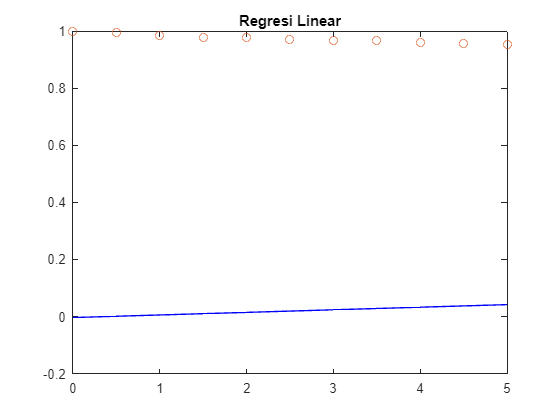


ln_y = zeros(1, 11); % Inisialisasi array untuk menyimpan nilai ln(y(x))

for i = 1:11
    ln_y(i) = log(C(1)) - C(2) * x(i); % Menggunakan rumus ln(y(x)) = ln(a) - bx
end

plot(x, ln_y, 'b', x, y, 'o');
title('Regresi Linear');